## What to do with Rascal Bayes Outputs.

The output for Bayes is saved as a normal Matlab struct variable. So it is as described here [https://www.mathworks.com/help/matlab/matlab_env/save-load-and-delete-workspace-variables.htm](https://www.mathworks.com/help/matlab/matlab_env/save-load-and-delete-workspace-variables.htm)

In this example, I've saved the output from the bayes plugin as 'demo.mat', so let's load that in....

out = load('demo.mat')

out = struct with fields:
    output: [1×1 struct]


...we then want out.output, which is a struct. We'll assign this to a new variable because it's convenient....

output = out.output

output = struct with fields:
    posteriors: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
      bestFits: [1×1 struct]
     intervals: [1×1 struct]
          data: {[51×3 double]  [51×3 double]  [51×3 double]  [51×3 double]  [51×3 double]  [51×3 double]  [51×3 double]}
    MCMCoutput: [1×1 struct]


Looking at these in turn. 'posteriors' is as it suggests. It is an array of structs, one for each parameter. Looking at the first one....

firstParam = output.posteriors{1}

firstParam = struct with fields:
         bins: [1×36 double]
    bincounts: [1×36 double]


(note the curly brackets syntax). We can then plot this if we need to....

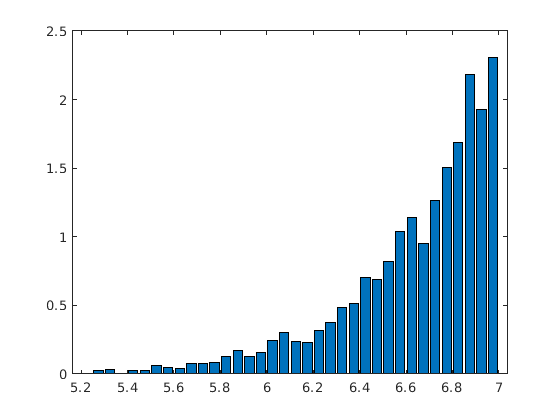

figure
bar(firstParam.bins, firstParam.bincounts)

'bestFits' contains exactly what it suggests....

output.bestFits

ans = struct with fields:
    bestFits: {[51×2 double]  [51×2 double]  [51×2 double]  [51×2 double]  [51×2 double]  [51×2 double]  [51×2 double]}
    bestSlds: {[176×2 double]  [176×2 double]  [176×2 double]  [176×2 double]  [176×2 double]  [176×2 double]  [176×2 double]}


...which is also a struct in itself. So to get access to the best fits for contrast 1, we go....

contrast1 = output.bestFits.bestFits{1}

contrast1 =     0.0518    0.0010
    0.0544    0.0009
    0.0571    0.0008
    0.0600    0.0007
    0.0630    0.0007
    0.0661    0.0006
    0.0694    0.0005
    0.0729    0.0005
    0.0765    0.0004
    0.0803    0.0004


..which we can then plot if we want..

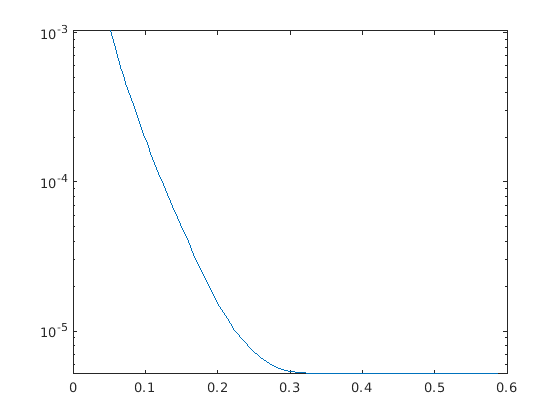

semilogy(contrast1(:,1),contrast1(:,2))

It's the same for the SLD's...

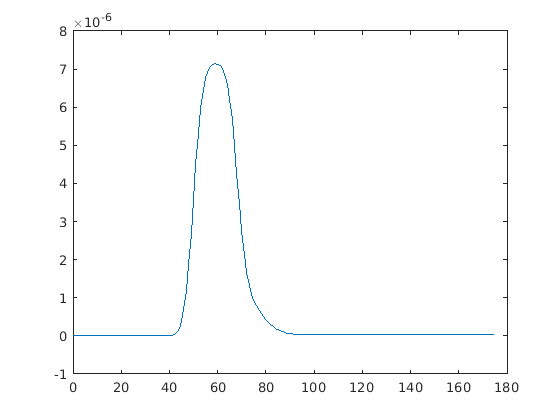

figure
contrast1SLD = output.bestFits.bestSlds{1};
plot(contrast1SLD(:,1),contrast1SLD(:,2))

The output for the shading is contained in 'output.intervals'....

output.intervals

ans = struct with fields:
    refShading_95: {[51×4 double]  [51×4 double]  [51×4 double]  [51×4 double]  [51×4 double]  [51×4 double]  [51×4 double]}
        values_95: [13×2 double]
    sldShading_95: {[176×4 double]  [176×4 double]  [176×4 double]  [176×4 double]  [176×4 double]  [176×4 double]  [176×4 double]}
       message_95: 'ok'
    refShading_65: {[51×4 double]  [51×4 double]  [51×4 double]  [51×4 double]  [51×4 double]  [51×4 double]  [51×4 double]}
        values_65: [13×2 double]
    sldShading_65: {[176×4 double]  [176×4 double]  [176×4 double]  [176×4 double]  [176×4 double]  [176×4 double]  [176×4 double]}
       message_65: 'ok'
    refShading_25: {[51×4 double]  [51×4 double]  [51×4 double]  [51×4 double]  [51×4 double]  [51×4 double]  [51×4 double]}
        values_25: [13×2 double]
    sldShading_25: {[176×4 double]  [176×4 double]  [176×4 double]  [176×4 double]  [176×4 double]  [176×4 double]  [176×4 double]}
       message_25: 'ok'


These are obviusly the relevant confidence intervals. So, to get the 95% interval for the first contrast we go....

thisContrast = output.intervals.refShading_95{1}

thisContrast =     0.0518    0.0010    0.0009    0.0012
    0.0544    0.0009    0.0008    0.0011
    0.0571    0.0008    0.0007    0.0010
    0.0600    0.0007    0.0006    0.0009
    0.0630    0.0007    0.0005    0.0008
    0.0661    0.0006    0.0005    0.0007
    0.0694    0.0005    0.0004    0.0006
    0.0729    0.0005    0.0004    0.0006
    0.0765    0.0004    0.0003    0.0005
    0.0803    0.0004    0.0003    0.0004


The first column is qz, the second best fit, and the other two min and max ranges.....

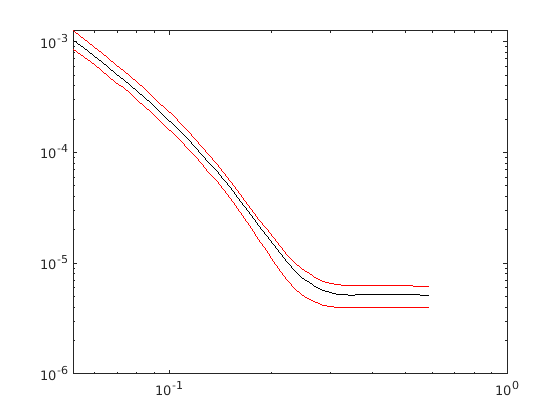

clf
loglog(thisContrast(:,1),thisContrast(:,2),'k-');
hold on
loglog(thisContrast(:,1),thisContrast(:,3),'r-');
loglog(thisContrast(:,1),thisContrast(:,4),'r-');

It's the same for the SLD's, which are in sldShading for each contrast.

Also in this struct are the best fit values....

These are the min and max values for each confifence interval...

output.intervals.values_95

ans =     6.4102    6.9997
   16.9846   19.0612
    0.0000    0.0000
    3.0004    4.5043
   -0.0000   -0.0000
    7.0002    7.9291
    0.0000    0.0000
    3.0002    3.7453
    0.0000    0.0000
    5.9606   11.1040


output.data has the datapoints corrected for scalefactor. Output.MCMCoutput has various diagnostics from the fit....

output.MCMCoutput

ans = struct with fields:
     results: [1×1 struct]
       chain: [10000×13 double]
     s2chain: []
     sschain: [10000×1 double]
    bestPars: [6.6407 17.7136 7.4447e-06 4.2421 -3.3034e-07 7.6323 5.6519e-06 3.3656 1.6701e-06 11.1040 3.0217e-06 5.1872e-06 0.2298]
        data: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}


bestPars has the best-fit parameters. From there you can output whatever you need into a .dat file - at the matlab prompt type 'help dlmwrite' which will give you the information you need.